# **Extract Celerity and depths**

Ce script permet d'extraire la célérité des vagues et la profondeur à partir des images timsestack croos-shore en utilisant la méthode d'inter-corrélation temporelle. On applique un critère de sélection d'image (images nettes et floues)  basé sur la largeur de l'écart-type de l'intensité de pixel au déferlement.

close all
clear all
clc

addpath('./Timestacks/Timestacks_15min/')
addpath(genpath('./'))
path = 'C:\Users\Rafael\MATLAB Drive\Senegal/Timestacks/Timestacks_15min/';
irect = 2;
load('rect_Jennifer.mat') % On charge le vecteur de distances cross-shore

- Select the range of dates you want to analyse format 'yyyymm' with quotations mark. For instances, all the images on August 2021 ('202108'):

Img = dir([path,strcat('**/S_3_*')]);

## Vectors to save the final parameters

- The script will compute parameters such as: Wave height (Hs), wave period (T_p1), wave celerity (C1), wave length (W1) and depth which cab be used to reconstruct the bathymetry over time. Figure 5 from Thuan et al., 2019 shows examples of these parameters.

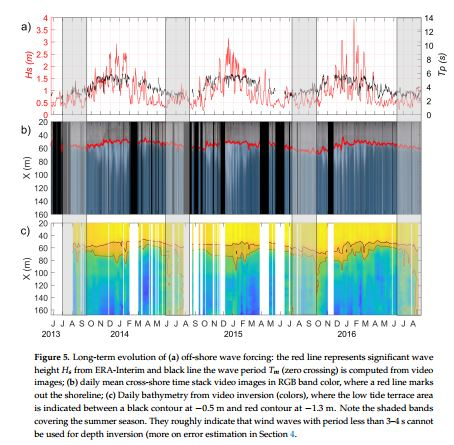

Hs = [];
T_p1 = [];
C1 = [];
WL1 = [];
depth1 = [];
t = [];

### Parameters for the image procesing

dt = 1/3; % dt=1/freq avec freq=3 (fréquence d'acquisition de la caméra : 3 images par seconde)
H_camera         = 18.888;             % Camera height [m]
sk1              =  [2500 1];       % St Louis chosen transect
sk2              =  [1250 4300];

% Parameters for Cross-correlation computation
Nlim=800; % original 400% Nombre d'échantillons à considérer (pour gain de temps) sur les 15 min de l'image, sachant que 15 min = 1800 échantillons
dpha=3; % On fixe le décalage temporelle "dpha"La littérature donne la période moyenne des vagues : GPP Tp=9.4 s.
% "dpha" est le décalage temporelle qui doit être inférieur à
% la période des vagues
%Ecartement max pour la cross-correlation
res=1;%res: resolution pour la cross-correlation %1 rafael
wdf=0.7;%largeur du filtre passe bande (en ratio)

cxx

%    1:length(Img)
for i = 1:length(Img)
    t = [t; datenum(Img(i).name(5:end-4),'yyyymmddHHMM')];
    % Step 1 : Load image
    fprintf('Image en cours de traitement %s\n',datestr(datenum(Img(i).name(5:16),'yyyymmddHHMM'),'mmmm dd, yyyy HH:MM AM'))
    S0=imread(Img(i).name); % Reading image !
    

### Original vs Rectified Timestack

- The original timestack obtained with the Script ***XXXX***, had a duration of ~ 1 min (S1_xxxx). With the script ***00_Merging_timestacks ***15 timestacks are merged and put in the right format for this script (S_3_yyyymmdd.jpg). Timestacks have a sample frequency of 3 Hz (3Hz x 15min x 60 sec = 2700 frames]. 

- dt=1/freq avec freq=3 (fréquence d'acquisition de la caméra : 3 images par seconde)

    figure(1)
    set(gcf, 'Position', [10 10 600 1200], 'Color', [1, 1, 1])
    subplot(211)
    image(S0)
    xlabel('X[Pixels]')
    ylabel('Frames')
    title(sprintf('%s',datestr(datenum(Img(i).name(5:16),'yyyymmddHHMM'),'mmmm dd, yyyy HH:MM AM')))
    set(gca, 'fontsize',14)
   
    if irect == 1
        % Step 2 : Rectified image
        [S0,resc]=rectify_stack_image(S0,diff(dxXX.*0.01)); % S0 = image rectifiée, resc = résolution spatiale en mètre de S0
        icmin=1; % Indice min sur l'axe des abcisses pour le pré-traitement
        icmax= 100; % Indice max sur l'axe des abcisses pour le pré-traitement
        dc=50; % see Thuan et al., 2019 and Abessolo et al., 2020 (Figure 2 above)
        xlabel1 = 'X [m]';
    else
        icmin=1; % Indice min sur l'axe des abcisses pour le pré-traitement
        icmax= 1000; % Indice max sur l'axe des abcisses pour le pré-traitement
        resc = 1;
        dc=200; % Indice max sur l'axe des abcisses pour le pré-traitement
        xlabel1 = 'X [pixels]';
    end

    [nt,nc,ncol]=size(S0);

    % Step 3 : Mise en forme de l'image
    So=double(S0);
    S_std=nanstd(So);

    % Step 4 : Délimitation de la zone de déferlement
    S_std0=smooth(S_std(:,:,3)); % On ne considère que la composante bleue
    % Je me limite au pixel 900 car il s'agit du haut de plage
    % On smoothe pour éliminer les pics aléatoires
    iS=find(S_std0>0.5*max(S_std0)); % Indices correspondants à
    %la zone de déferlement (after rafael comment)

    subplot(212)
    image(S0)
    box on
    % Affichage de la zone de déferlement (Critère de
    % déferlement)
    hold on
    plot(smooth(S_std(:,:,1),30).*40,'r')
    plot(smooth(S_std(:,:,2),30).*40,'g')
    plot(smooth(S_std(:,:,3),30).*40,'b')
    xlim([1 size(S0,2)])
    patch([min(iS) min(iS)],[0 size(S0,1)],'k','Linewidth',2)
    patch([max(iS) max(iS)],[0 size(S0,1)],'k','Linewidth',2)
    hold off
    box on
    xlabel(xlabel1)
    ylabel('Frames')
    set(gca, 'fontsize',14)
    clear S0

    S0=double(So(:,:,3)); % On ne considère que la composante "bleue" pour le pré-traitement
    S1=S0(1:min([Nlim size(S0,1)]),:);

    % Step 4 : Pré-Traitement de l'image (élimination de la
    % redondance spatiale et du bruit, pour ne conserver que le
    % mouvement des vagues)
    % De ce que j'observe, "methodPreT=1" est la meilleure et c'est celle choisie par Almar
    [S2]=ImagePreProcessing_20090121Taller(S1,icmin,icmax,dt,resc,1);

### Computing correlation Matrix RM 

- The quality of the parameters compute with this script highly rely on the quality of the timestack, therefore, the correlation matrix. Ideally, a "good" correlation matrix look like the one in panel b. Figure taken from Thuan et al., 2019.

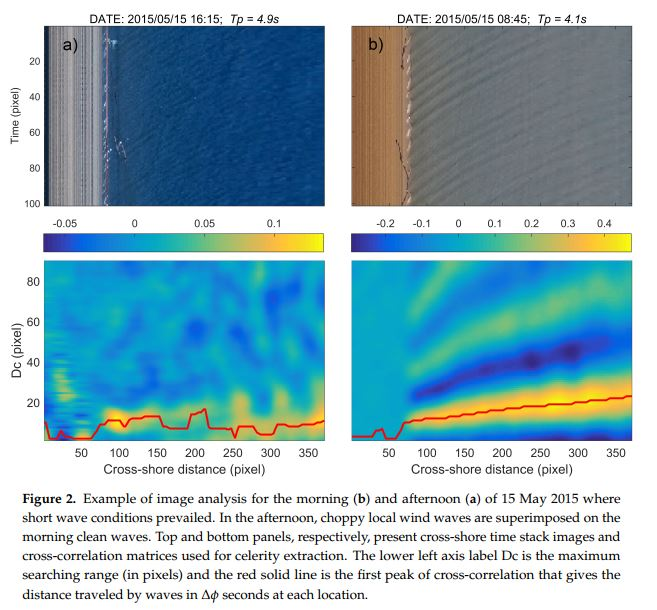

Better explanation about the wave parameter computation can be found in Abessolo et al., 2020.

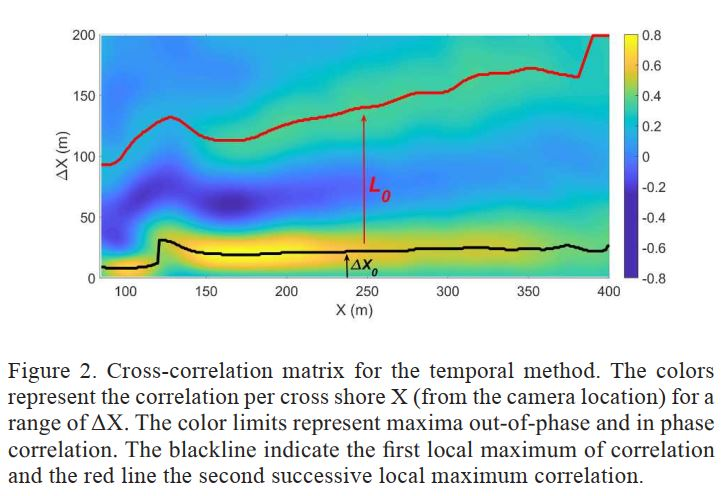

    % Step 5: Cross-correlation computation
    try
    [Cf1,WLe1,Tp1,Hs1,RM]=croscor_20180904_modv2(S2,dpha,dt,dc);
    Depthf1 = (Cf1.^2)/9.81;

### Visualization of the correlation Matrix RM for the current date

    a=1:size(RM,1);
    b=1:size(RM,2);
    [A,B]=meshgrid(a,b);

    figure
    clf
    set(gcf,'Color','w')
    surface(A,B,RM');
    shading flat
    colorbar;
    xlabel(xlabel1)
    ylabel('Dc')
    set(gca, 'fontsize',14)

### Visualization of computed parameters

    figure(103)
    clf
    set(gcf,'Color','w')
    subplot(4,1,1)
    plot(Tp1(min(iS):end),'k');ylabel('T (s)')
    subplot(4,1,2)
    plot(WLe1,'k');ylabel('L (m)')
    subplot(4,1,3)
    plot(Cf1,'k');ylabel('C (m/s)')
    subplot(4,1,4)
    plot(Depthf1,'k');ylabel('Depth (m)')
    xlabel(xlabel1)

    Cf1 = nanmean(Cf1(find(Cf1>0)));
    Tp1 = nanmean(Tp1(find(Tp1>0)));
    WLe1 = nanmean(WLe1(find(WLe1>0)));
    Hs1 = nanmean(Hs1(find(Hs1>0)));
    catch
        Cf1 = NaN;
        WLe1 = NaN;
        Tp1 = NaN;
        Hs1 = NaN;
        Depthf1 = NaN;
    end
    C1=[C1 Cf1']; % Sauvegarde du vecteur de célérité
    WL1=[WL1 WLe1']; % Sauvegarde du vecteur Wavelength
    T_p1=[T_p1 Tp1']; % Sauvegarde des périodes peak
    Hs =[Hs Hs1'];
    depth1=[depth1 Depthf1];

    clear Cf1 WLe1 Tp1 Hs1 RM Depthf1

end

### Table with the computed wave parameters

Time = datetime(t(:),'ConvertFrom','datenum');
WP = timetable(Time, Hs(:), T_p1(:), C1(:), WL1(:));
WP_daily = retime(WP, 'daily', 'mean');
WP_daily.Properties.VariableNames = {'Hs' 'Tp' 'Celerity' 'Wavelength'};


WP_daily =

  0×4 empty timetable



WP_daily

### Wave Parameters compute with the camera

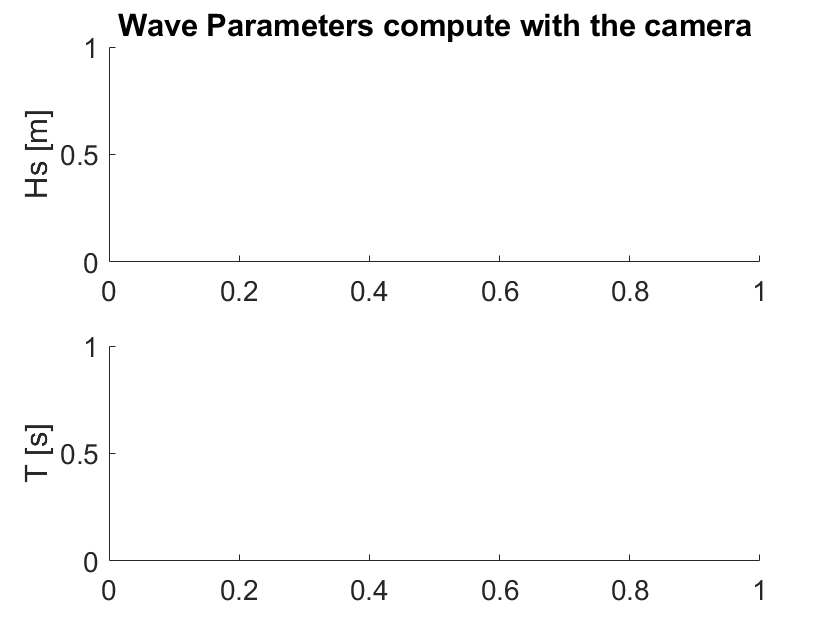

figure
subplot(211)
plot(WP.Time,WP.Var1, 'o:k')
hold on
plot(WP_daily.Time,WP_daily.Hs,'o-k','MarkerFace','r')
ylabel('Hs [m]')
title('Wave Parameters compute with the camera')
set(gca, 'fontsize',14)

subplot(212)
plot(WP.Time,WP.Var2, 'o:k')
hold on
plot(WP_daily.Time,WP_daily.Tp,'o-k','MarkerFace','r')
ylabel('T [s]')

set(gca, 'fontsize',14)


### Measure data for August 2021. Taken from Wind guru (Dakar)

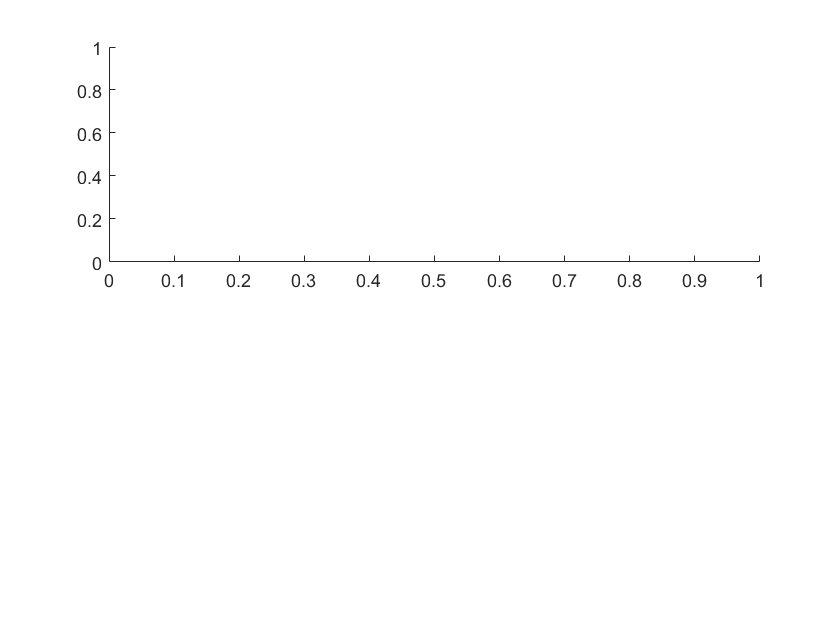

Hs_m = [1.4 1.3 2.1 1.7 1.5 1.4 1.7 1.4 1.3 1.1];
Tp_m = [7 8 7 14 13 13 8 7 7 7];

figure

subplot(211)

Error using plot
Vectors must be the same length.

plot(WP_daily.Time,Hs_m,'o-k','MarkerFace','r')
ylabel('Hs [m]')
title('Measured Wave Parameters')
set(gca, 'fontsize',14)

subplot(212)
plot(WP_daily.Time,Tp_m,'o-k','MarkerFace','r')
ylabel('T [s]')
set(gca, 'fontsize',14)